This code was used for producing graphs for my senior project report. It contains some different tests for the code. CGLS still does not work in the multichannel case. 

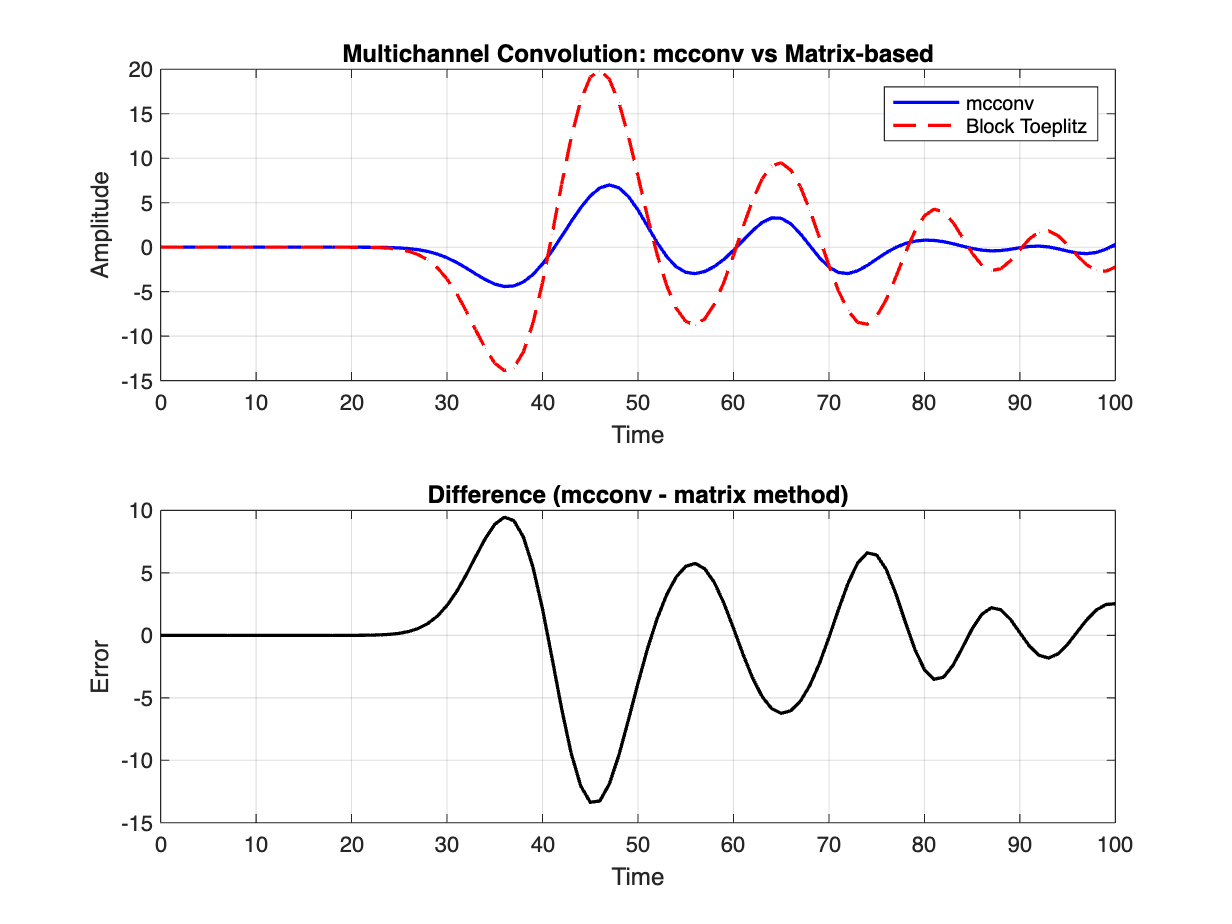


clear


% Defining time grid
K = 101; %number of time points on base grid
T = 100;
dt = T/(K-1);

t_grid = linspace(0,T,K); %base grid
t_grid_ext = linspace(-T+dt,T,2*K-1); %extended grid for plotting Green's function

% Generating Green's function
rng('default') %fixing seeding so that the same random number is generated everytime
G = rand(K,1);
G = round(G);
%G = [zeros(K-1,1); G]; %padding with zeros to extend domain of G


% Generating source time function
fpeak = 0.05; %peak frequency
tc = 40; %center point
w = RickerWave(t_grid,tc,fpeak)';


Test 1: Simple Convolution FFT vs Mat Mult.

d_sc = simpleconv(w,G);

G = [zeros(K-1,1); G];
A_row = dt*G(K:-1:1); 
A_col = dt*G(K:end);
A = toeplitz(A_col,A_row);

d_mm = A*w;

diff = d_sc - d_mm % great success!

figure;
tiledlayout(2,1)

% signals comparison 
nexttile
plot(t_grid, d_sc, 'b', 'LineWidth', 1.5); hold on
plot(t_grid, d_mm, 'r--', 'LineWidth', 1.5);
grid on
xlabel('Time')
ylabel('Amplitude')
title('Convolution Comparison: FFT-based vs Matrix-based')
legend('FFT / simpleconv', 'Toeplitz matrix method')

% difference
nexttile
plot(t_grid, diff, 'k', 'LineWidth', 1.5);
grid on
xlabel('Time')
ylabel('Error')
title('Difference (simpleconv - matrix method)')

figure;
plot(t_grid, abs(diff), 'm', 'LineWidth', 1.5);
grid on
xlabel('Time')
ylabel('|Error|')
title('Absolute Error Between Methods')

Test 2: Multipole Convolution vs Mat. Mult.

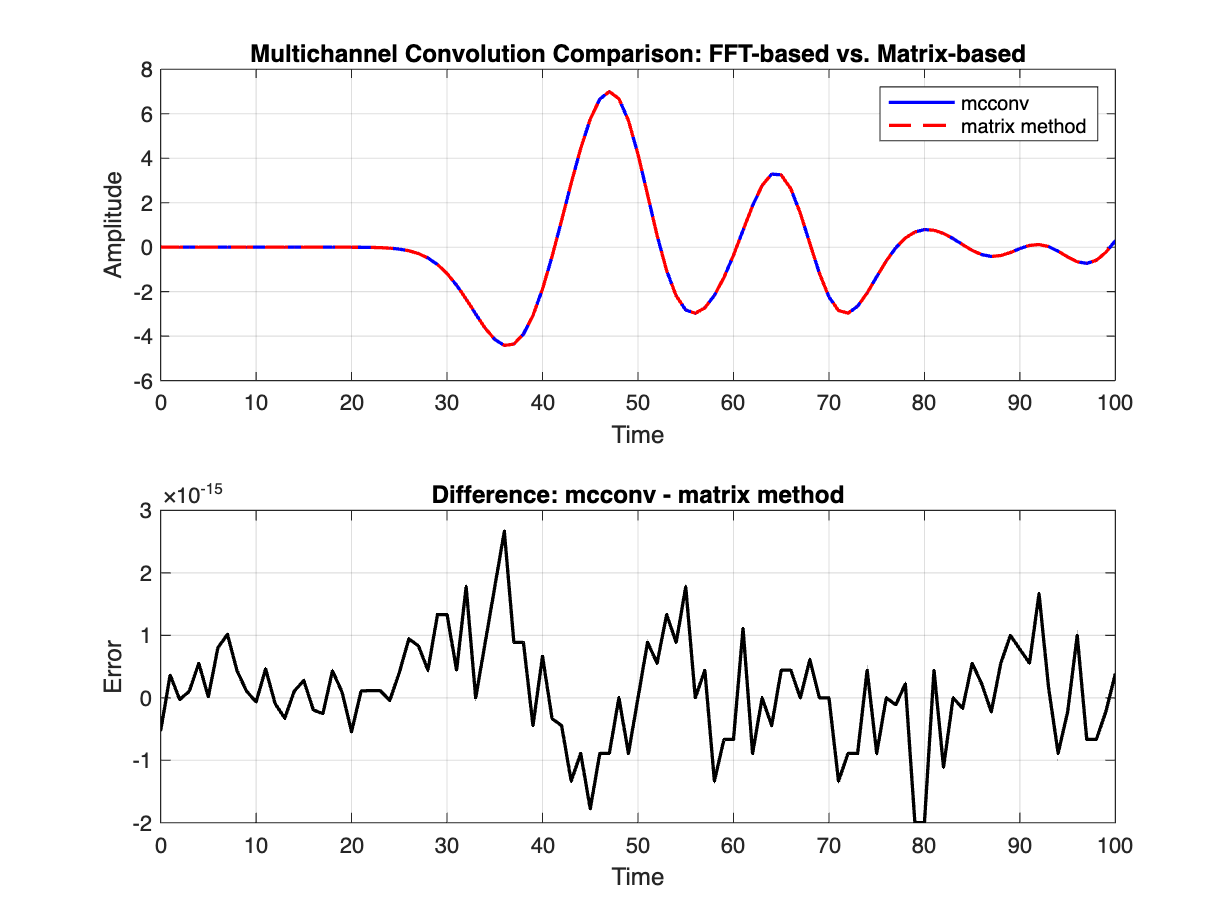

clear

% Defining time grid
K = 101;
T = 100;
dt = T/(K-1);

t_grid = linspace(0,T,K);

% Number of channels
C = 3;

% Green's functions (one per channel)
rng('default')
G = round(rand(K,C));

% Source signals (multichannel)
fpeak = 0.05;
tc = 40;

w = zeros(K,C);
for c = 1:C
    w(:,c) = RickerWave(t_grid, tc + 2*(c-1), fpeak);
end

%% mcconv output
d_mc = mcconv(w, G);

%% Matrix-based multichannel convolution (correct form)

d_mm = zeros(K,1);

for c = 1:C

    g = G(:,c);
    g = [zeros(K-1,1); g];

    A_row = dt * g(K:-1:1);
    A_col = dt * g(K:end);

    A = toeplitz(A_col, A_row);

    d_mm = d_mm + A * w(:,c);
end

diff = d_mc - d_mm;

%% Plot comparison

figure;
tiledlayout(2,1)

nexttile
plot(t_grid, d_mc, 'b', 'LineWidth', 1.5); hold on
plot(t_grid, d_mm, 'r--', 'LineWidth', 1.5);
grid on
xlabel('Time')
ylabel('Amplitude')
title('Multichannel Convolution Comparison: FFT-based vs. Matrix-based')
legend('mcconv', 'matrix method')

nexttile
plot(t_grid, diff, 'k', 'LineWidth', 1.5);
grid on
xlabel('Time')
ylabel('Error')
title('Difference: mcconv - matrix method')

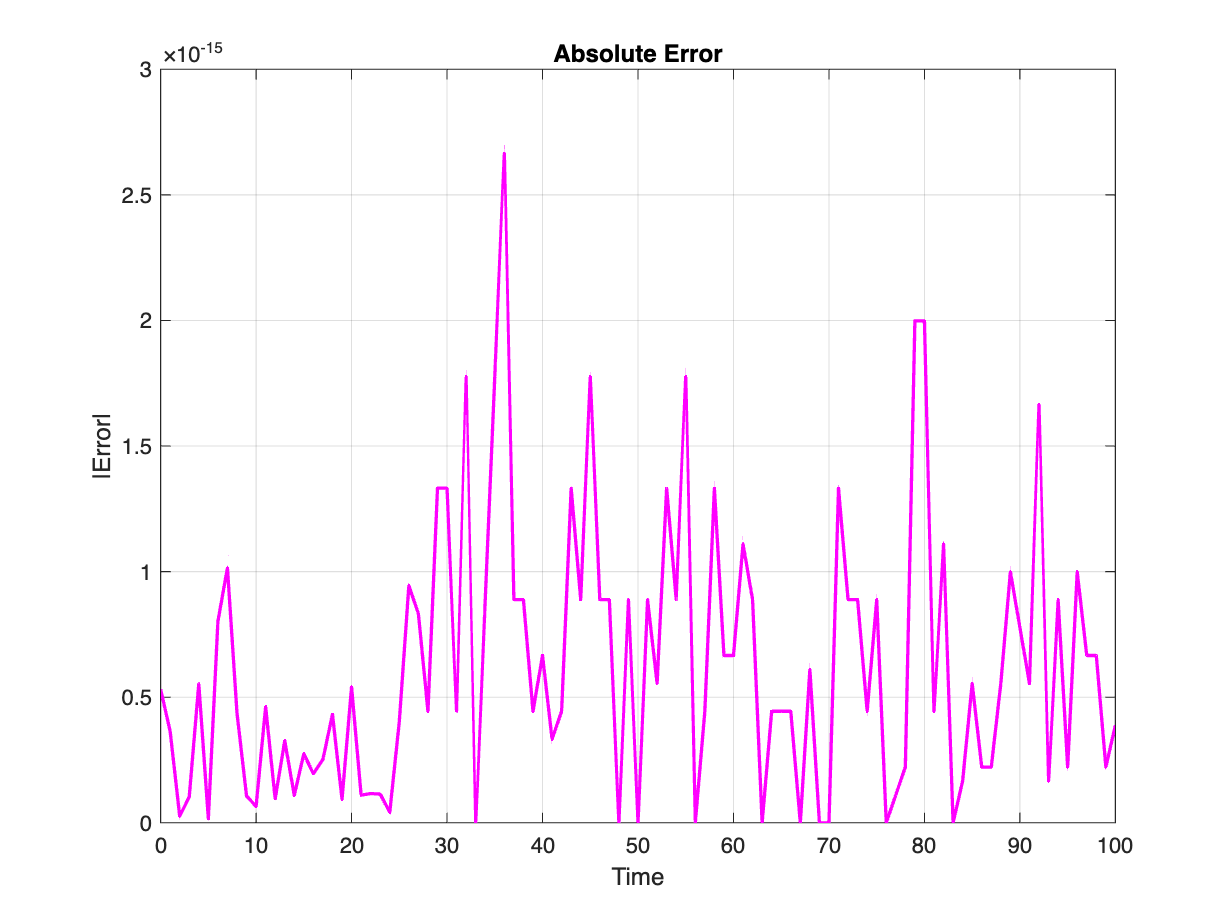


figure;
plot(t_grid, abs(diff), 'm', 'LineWidth', 1.5);
grid on
xlabel('Time')
ylabel('|Error|')
title('Absolute Error')

Test 3: Simple Convolution Adjoint 

clear
x = rand (101,1);
y = rand(101, 1);
rng('default') %fixing seeding so that the same random number is generated everytime
K = 101;
G = rand(K,1);
G = round(G);

A = @(x) simpleconv(x,G);
AT = @(x) simpleconv_adj (x,G);
diff = dot(A(x), y) - dot(x, AT(y)) % great success!!

diff = 0

Adjoint test:


  <Ax, y>   = 0.0000000000000000e+00


  <x, A^*y> = 0.0000000000000000e+00


  Relative error = 0.000e+00


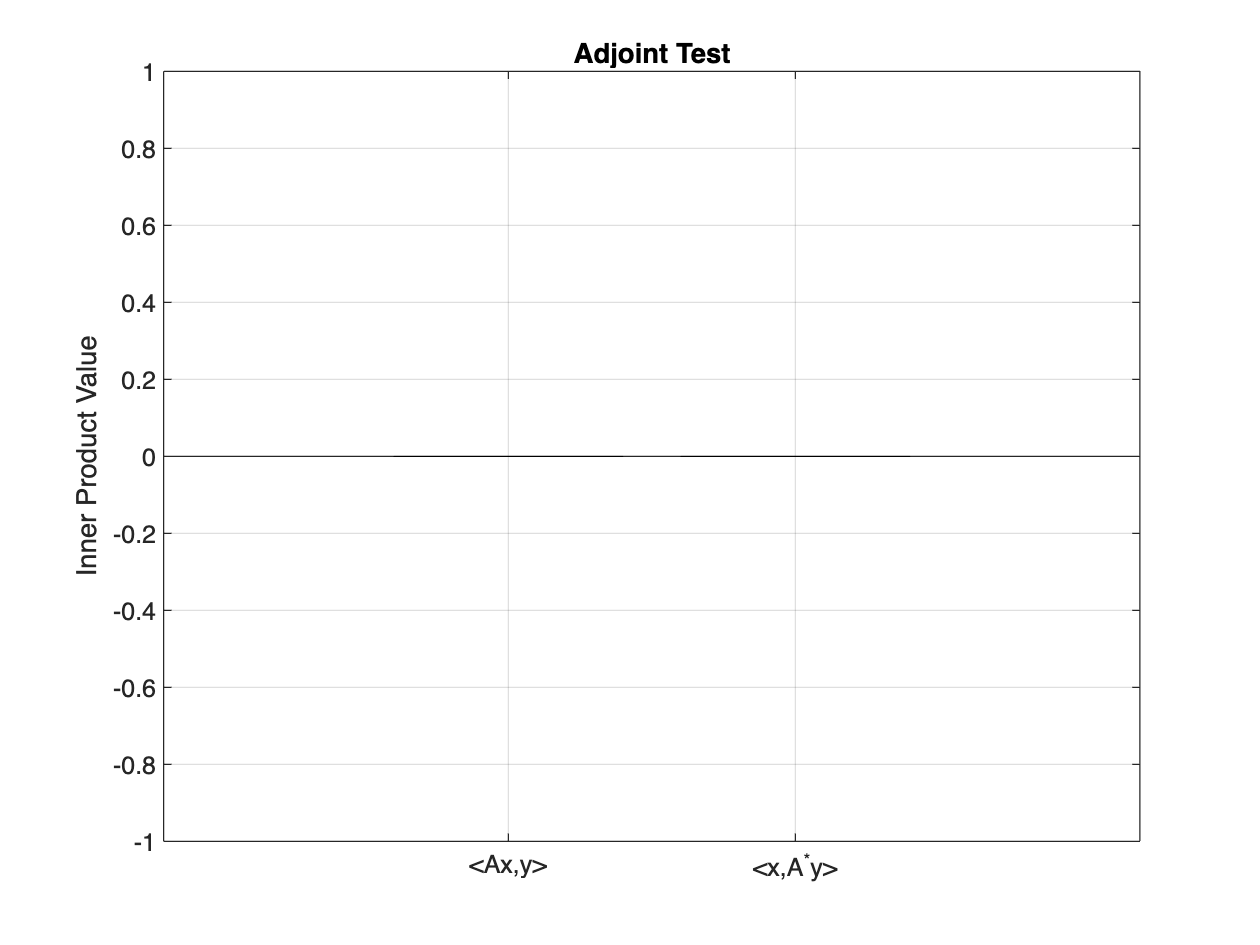

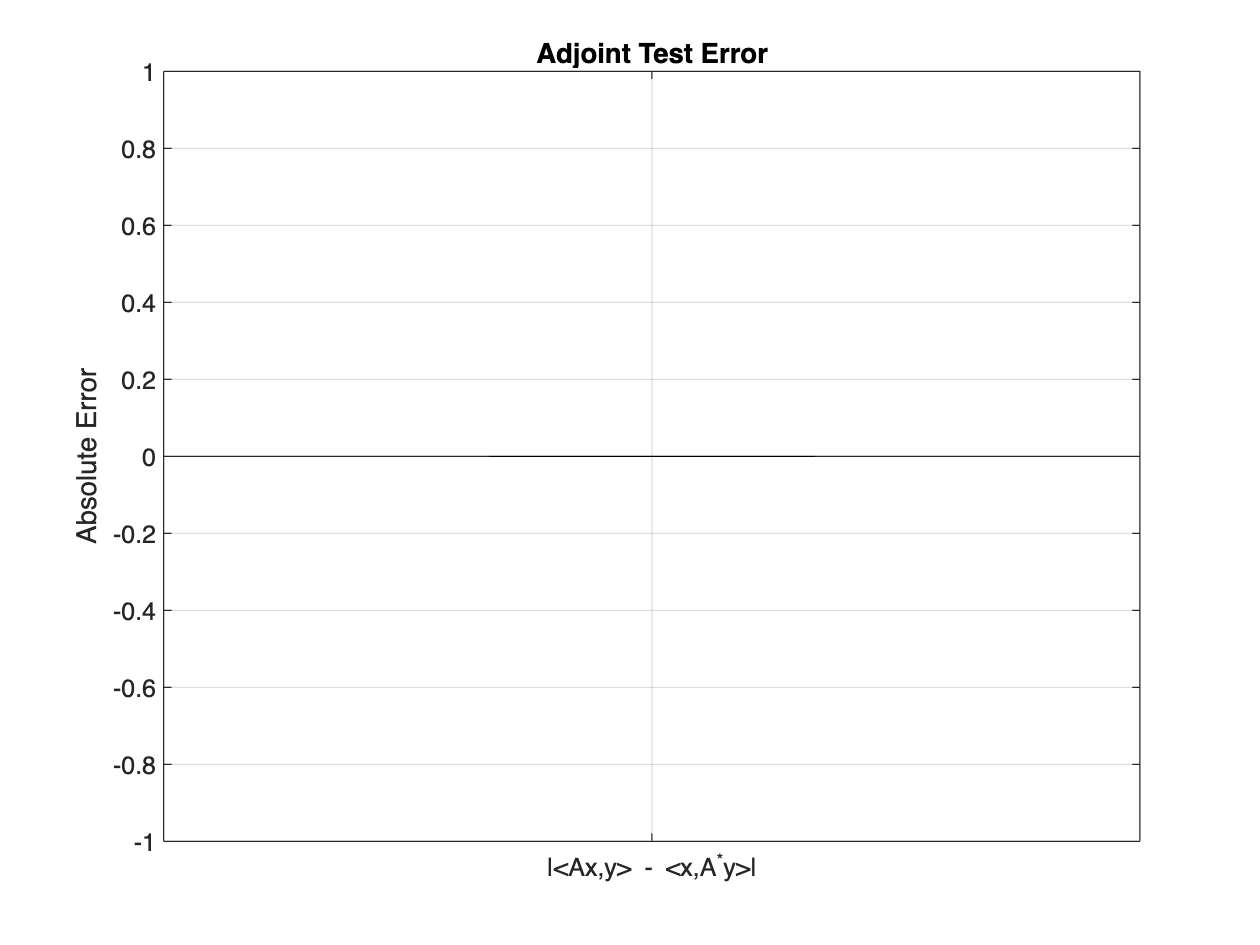


x = randn(K,1);      % model vector
y = randn(K,1);      % data vector

Ax  = simpleconv(x, G(K:end));   % forward operator
ATy = mcconv_adj(y, G(K:end));   % adjoint operator

lhs = y' * Ax;
rhs = x' * ATy;

abs_error = abs(lhs - rhs);


% Multiple random trials
ntrials = 50;
errors = zeros(ntrials,1);

for k = 1:ntrials
    x = randn(K,1);
    y = randn(K,1);

    Ax  = simpleconv(x, G);
    ATy = simpleconv_adj(y, G);

    lhs = y' * Ax;
    rhs = x' * ATy;

    errors(k) = abs(lhs - rhs) / max(abs(lhs), abs(rhs));
end

fprintf('Maximum relative error over %d trials: %.3e\n', ...
        ntrials, max(errors));

Maximum relative error over 50 trials: 5.597e-15


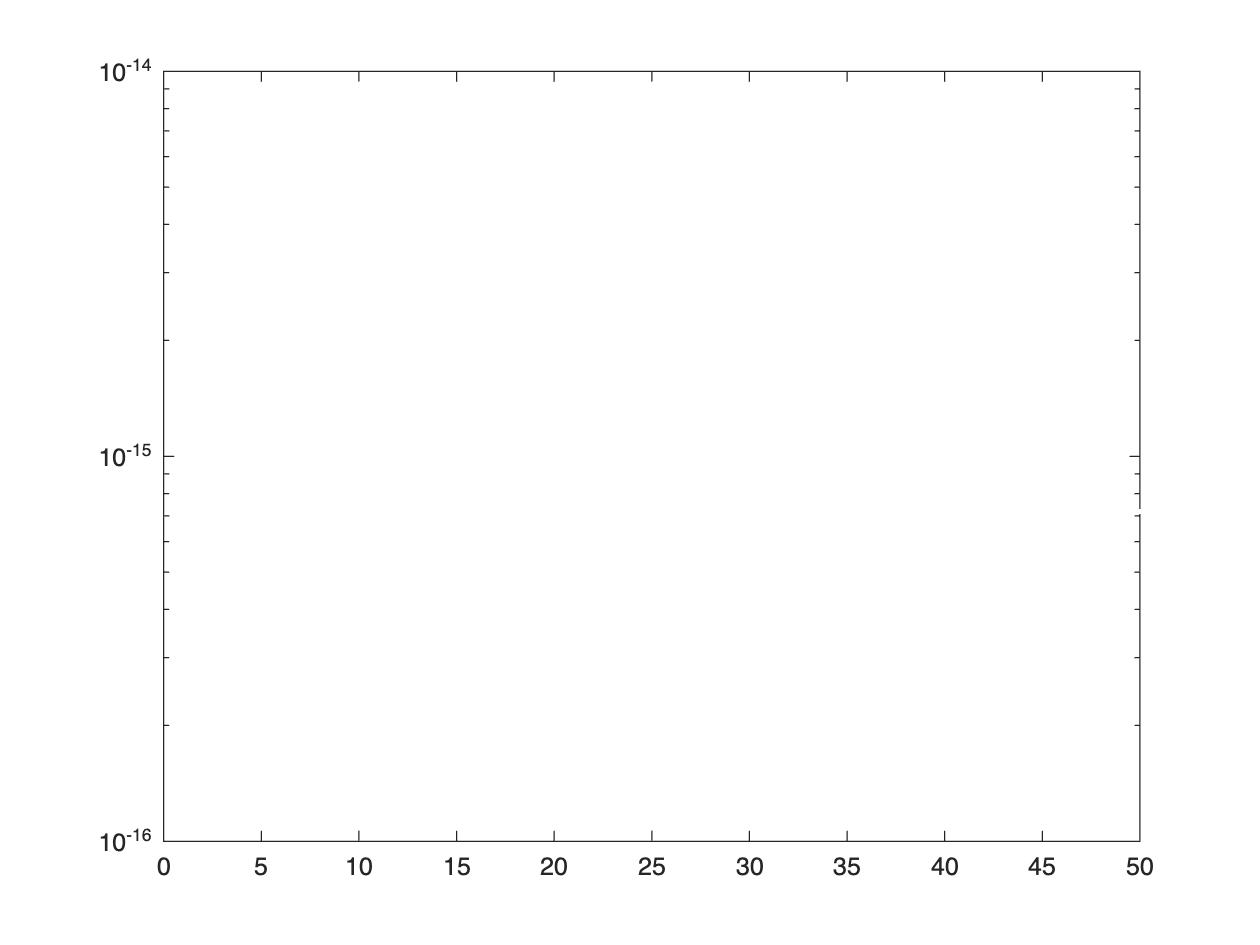


% Relative errors over trials
figure;
semilogy(1:ntrials, max(errors, eps) .* ones(size(errors)), 'w.'); % initialize axis

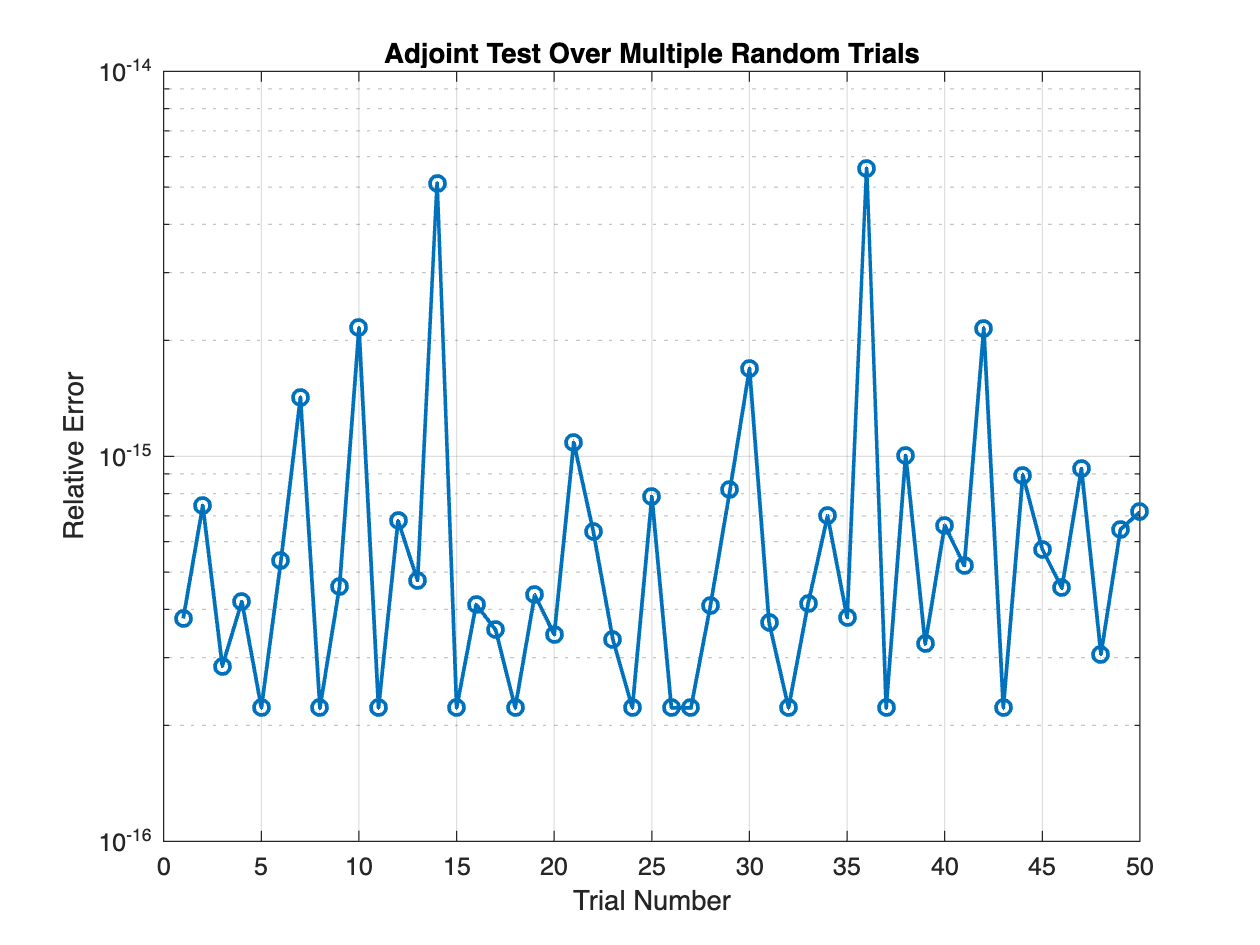

semilogy(1:ntrials, max(errors, eps), 'o-', 'LineWidth', 1.5);
grid on;
xlabel('Trial Number');
ylabel('Relative Error');
title('Adjoint Test Over Multiple Random Trials');


% Ensure y-axis is valid even if all errors are exactly zero
if all(errors == 0)
    ylim([1e-16 1]);
end

Test 4: Multichannel Convolution Adjoint

clear

n = 64;        % Signal length
m = 9;         % Kernel length
C = 3;         % Number of channels


rng('default');            
x = randn(n, C);           % Model (one column per channel)
y = randn(n, 1);           % Data
G = randn(m, C);           % Multichannel kernels

%% Define operators
A  = @(x) mcconv(x, G);
AT = @(y) mcconv_adj(y, G);

%% Apply forward and adjoint
Ax  = A(x);      % n x 1
ATy = AT(y);     % n x C

%% Compute inner products
lhs = sum(Ax .* y);              % <Ax, y>
rhs = sum(x .* ATy, 'all');      % <x, A^T y>

%% Errors
abs_error = abs(lhs - rhs);
rel_error = abs_error / max(abs(lhs), abs(rhs));

%% Print results
fprintf('Multichannel Adjoint Test\n');

Multichannel Adjoint Test


fprintf('-------------------------\n');

-------------------------


fprintf('<Ax, y>      = %.16e\n', lhs);

<Ax, y>      = 1.7197029537559342e+01


fprintf('<x, A^T y>   = %.16e\n', rhs);

<x, A^T y>   = 1.7197029537559352e+01


fprintf('Absolute err = %.16e\n', abs_error);

Absolute err = 1.0658141036401503e-14


fprintf('Relative err = %.3e\n\n', rel_error);

Relative err = 6.198e-16




% Relative error over multiple random trials
ntrials = 50;
errors = zeros(ntrials,1);

for k = 1:ntrials
    x = randn(n, C);
    y = randn(n, 1);

    Ax  = A(x);
    ATy = AT(y);

    lhs = sum(Ax .* y);
    rhs = sum(x .* ATy, 'all');

    errors(k) = abs(lhs - rhs) / max(abs(lhs), abs(rhs));
end

fprintf('Maximum relative error over %d trials: %.3e\n', ...
        ntrials, max(errors));

Maximum relative error over 50 trials: 2.220e-14


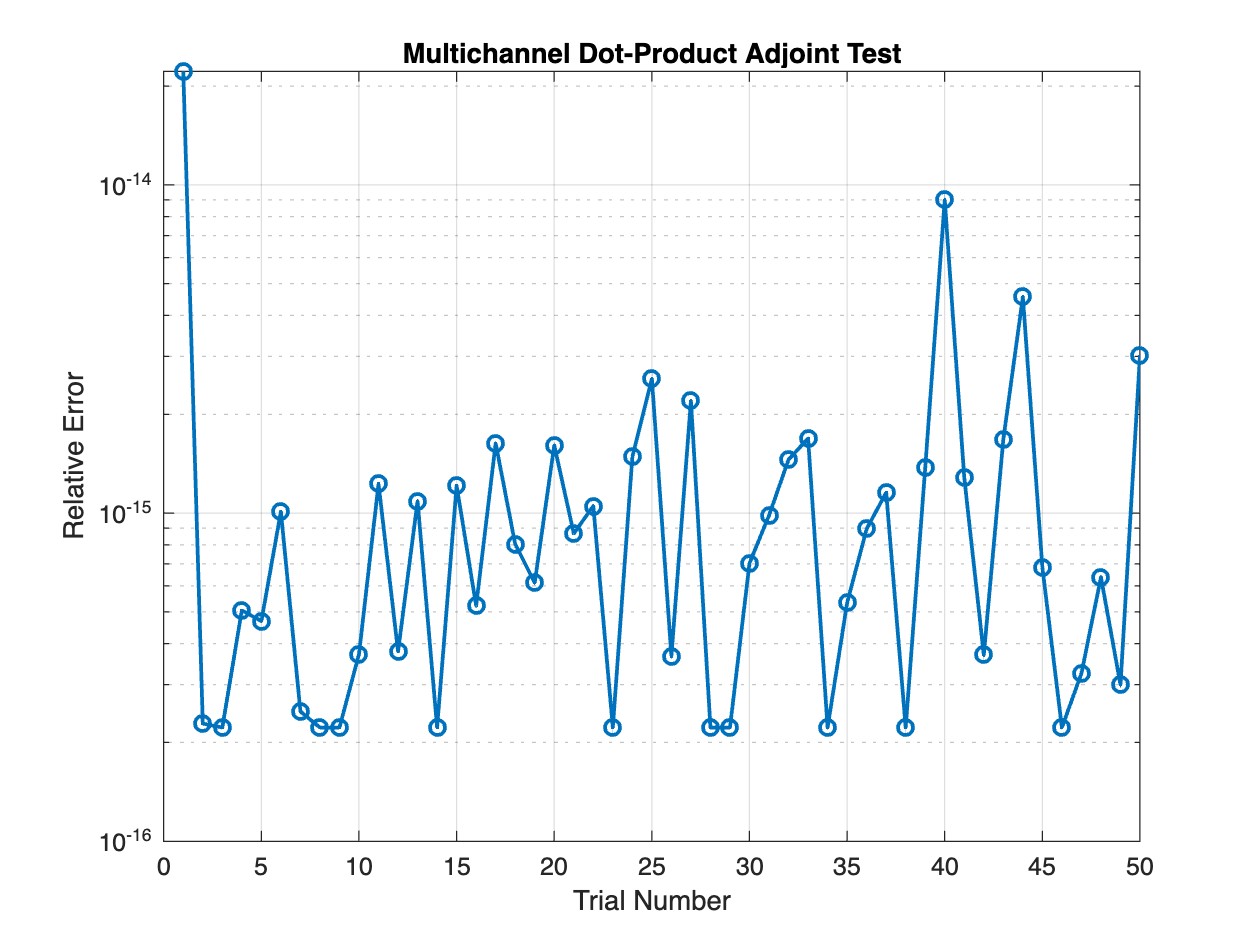


figure;
semilogy(1:ntrials, max(errors, eps), 'o-', 'LineWidth', 1.5);
grid on;
xlabel('Trial Number');
ylabel('Relative Error');
title('Multichannel Dot-Product Adjoint Test');


if all(errors == 0)
    ylim([1e-16 1]);
end

Test 5: Simple Inversion with CGLS (no simpleconv, just mat mult)

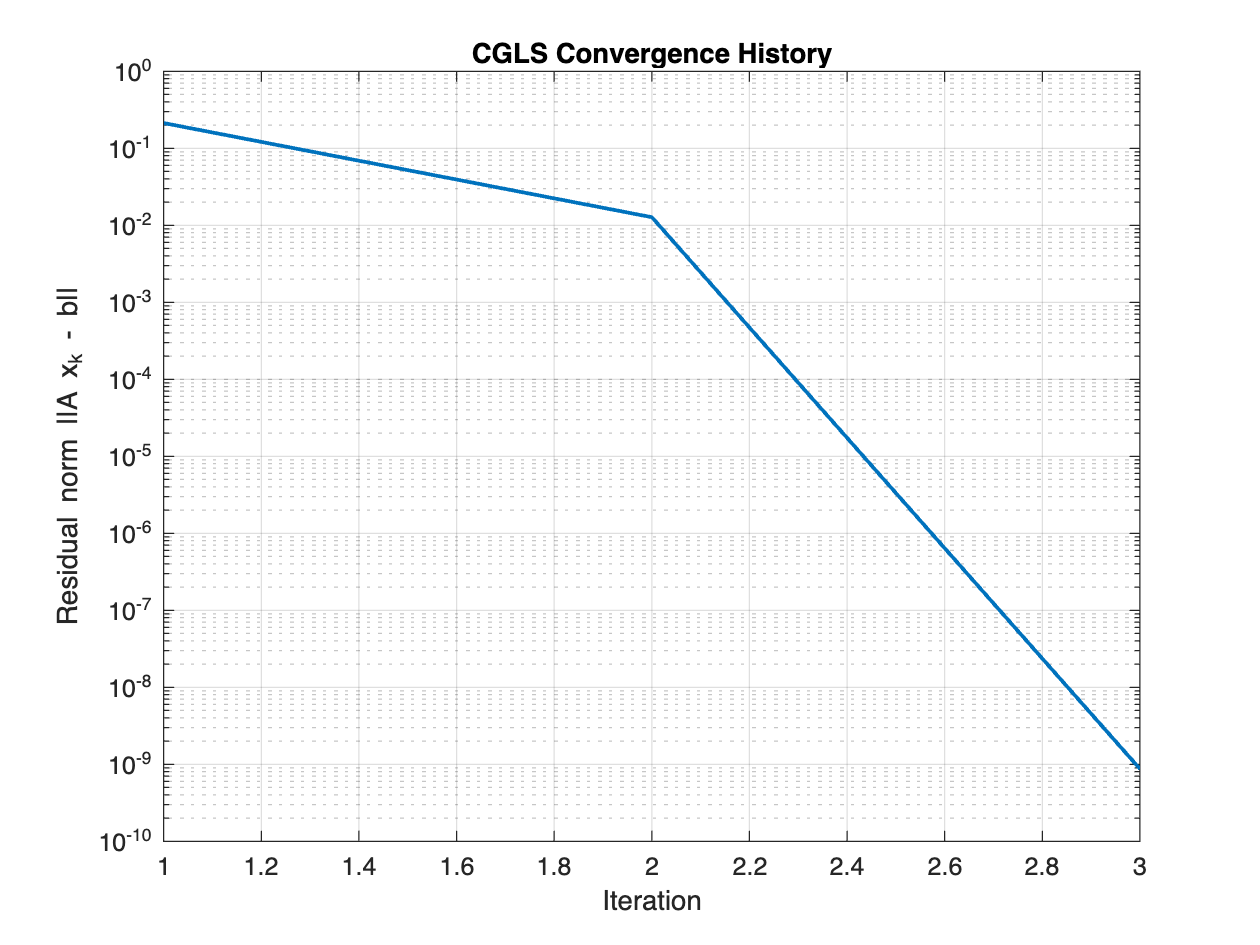

A_mat = [1 2 3; 4 5 6; 7 8 8];
A = @(x) A_mat*x;
AT_mat = [1 4 7; 2 5 8; 3 6 8];
AT = @(x) AT_mat*x;
d = [1; 2; 3];
x0 = zeros(size(d));
tol = 1e-4;
maxit = 500;


[x,~,res_hist] = CGLS(A,AT,d,x0,tol,maxit);

x_true = A_mat\d;
figure;
semilogy(res_hist, 'LineWidth', 1.5);
grid on;

xlabel('Iteration');
ylabel('Residual norm ||A x_k - b||');
title('CGLS Convergence History');


diff = x - x_true % great success!!

diff = 1.0e-11 *

    0.1613
    0.1925
    0.2082


Test 6: Multichannel Inversion with CGLS

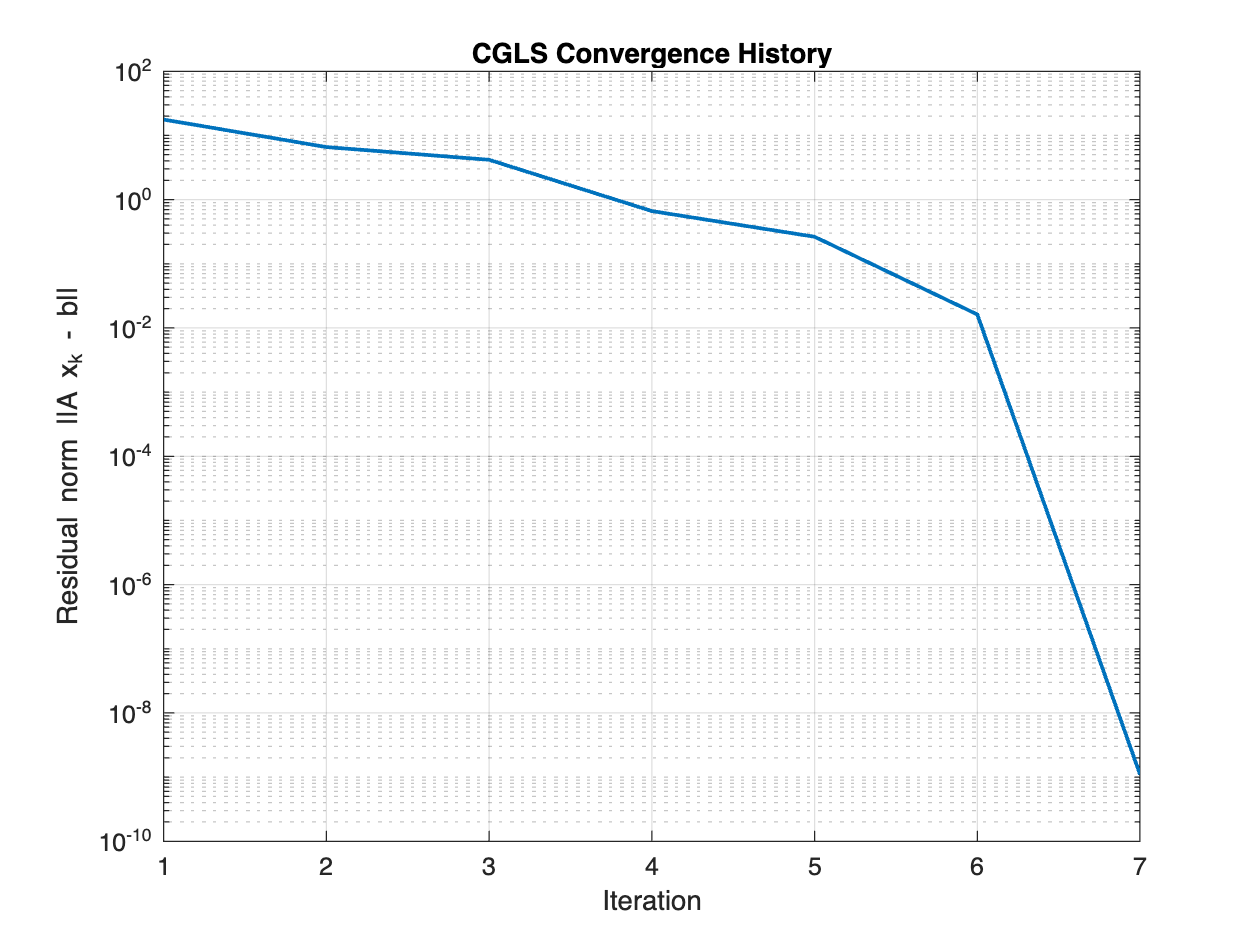

clear


n = 5;     % associated with w
m = 3;     % associated with G
Cin = 2;   % number of channels

%% True signal
w = [1  2;
     2  0;
     3  1;
     4  2;
     5  1];   % 5 x 2

%% green's functions (one per channel)
G = [1 2;
     2 1;
     1 0];   % 3 x 2

%% Build block convolution matrix A using toeplitz
L = n + m - 1;

A = zeros(L, n*Cin);

for c = 1:Cin

    gc = G(:,c);
    
    L = n + m - 1;

    % First column (padded kernel)
    col = [gc; zeros(L - m, 1)];

    % First row (shift structure)
    row = [gc(1), zeros(1, n-1)];

    % Build Toeplitz convolution matrix
    Tc = toeplitz(col, row);   % (L x n)

    % Insert into block operator
    cols = (c-1)*n + (1:n);
    A(:, cols) = Tc;

end

%% Flatten input
x_true = w(:);   % (n*Cin x 1)

%% Forward model
d = A * x_true;

%% Add small noise (optional test for CGLS robustness)
% d = d + 1e-3*randn(size(d));

%% Define operators for CGLS
A_f  = @(x) A*x;
AT_f = @(x) A'*x;

%% Initial guess
x0 = zeros(size(x_true));

%% Solve with CGLS
tol = 1e-6;
maxit = 200;

[x, ~, res_hist] = CGLS(A_f, AT_f, d, x0, tol, maxit);
figure;
semilogy(res_hist, 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('Residual norm ||A x_k - b||');
title('CGLS Convergence History');


diff = x - x_true

diff =    -0.0167
   -0.2083
   -0.7167
   -0.3083
    0.0000
    0.0083
    0.1167
    0.5167
    0.7167
    0.3083


fprintf('Residual: %.3e\n', norm(A*x - d)); % success ish

Residual: 2.329e-10


Test 5B: Simple Deconvolution with CGLS + simpleconv

G = rand(101,1);
G = round(G);
A = @(x) simpleconv(x,G);
AT = @(x) simpleconv_adj(x,G);
d = rand(101,1);
x0 = zeros(size(d));
tol = 1e-4;
maxit = 5000;

[x,iter,res_hist] = CGLS(A,AT,d,x0,tol,maxit)

x =     0.3225
    0.1091
    0.1019
    0.4074
    0.0836
    0.1759
    0.0298
   -0.2442
   -0.2534
   -0.0050


iter = 355

res_hist =    20.8629
    8.1469
    5.5082
    3.5824
    2.2836
    1.6105
    1.7090
    1.3265
    1.4510
    1.4942


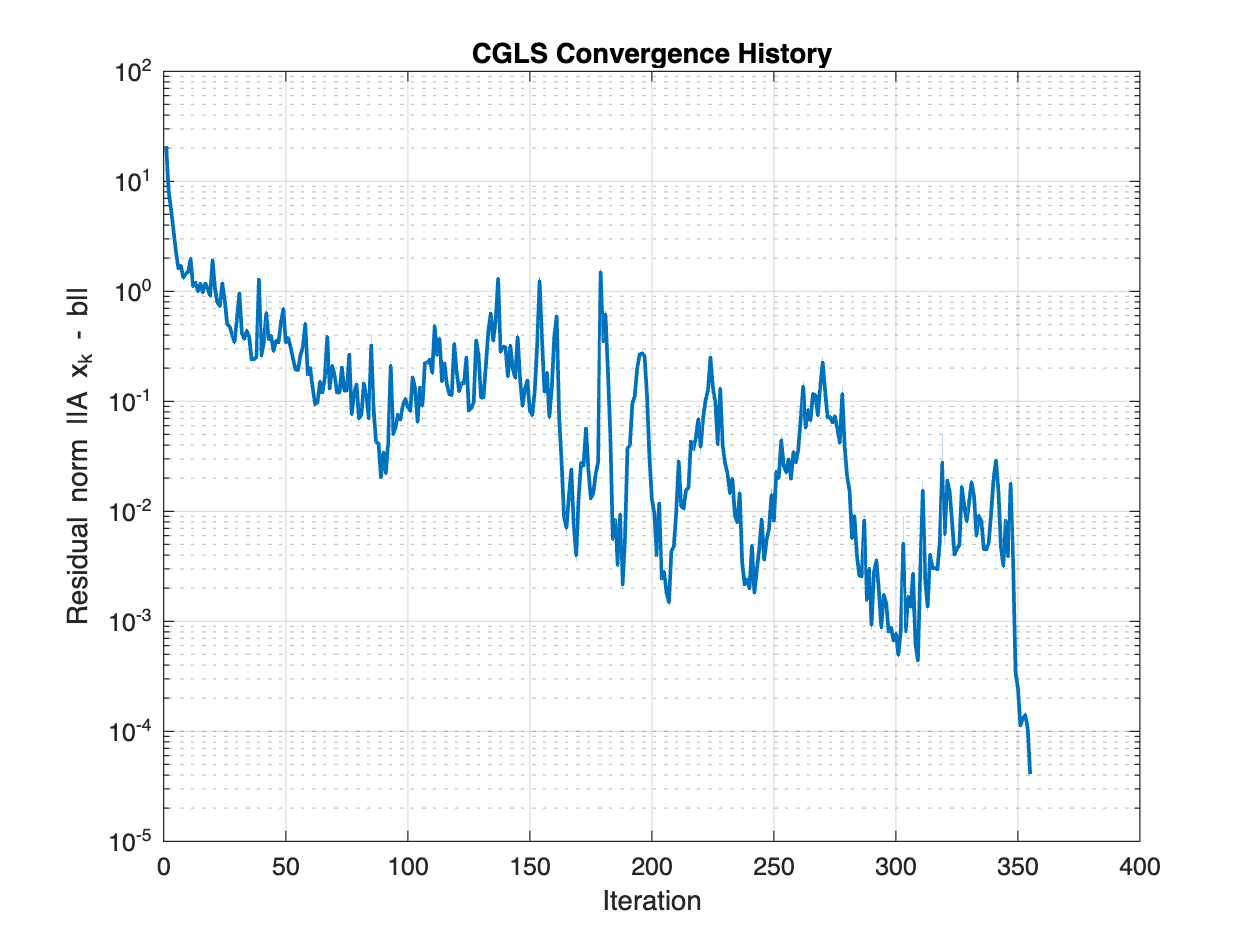


figure;
semilogy(res_hist, 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('Residual norm ||A x_k - b||');
title('CGLS Convergence History'); % wowie that is slow!! 

Test 6B: Multichannel Deconvolution with CGLS + mcconv

clear


n = 5;     % associated with w
m = 3;     % associated with G
Cin = 2;   % number of channels

%% True signal
w = [1  2;
     2  7;
     3  1;
     4  2;
     5  1];   % 5 x 2

%% green's functions (one per channel)
G = [1 2;
     2 1;
     1 0];   % 3 x 2

%% Define operators for CGLS
A  = @(x) mcconv(x,G);
AT = @(x) mcconv_adj(x,G);

%% Forward model
d = A(w);


%% Initial guess
x0 = zeros(size(w));

%% Solve with CGLS
tol = 1e-6;
maxit = 500;

[x, ~, res_hist] = CGLS(A, AT, d, x0, tol, maxit);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Error in CGLS (line 33)
        x = x + (alpha * p);

Related documentation

figure;
semilogy(res_hist, 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('Residual norm ||A x_k - b||');
title('CGLS Convergence History'); % success?

diff = x - w

Test 6C: Another Multipole example!

Great Sucess!

function [vals] = RickerWave(t_grid,tc,fpeak)

vals = (1-2*((t_grid-tc)*pi*fpeak).^2).* exp( -((t_grid-tc)*pi*fpeak).^2 );

end